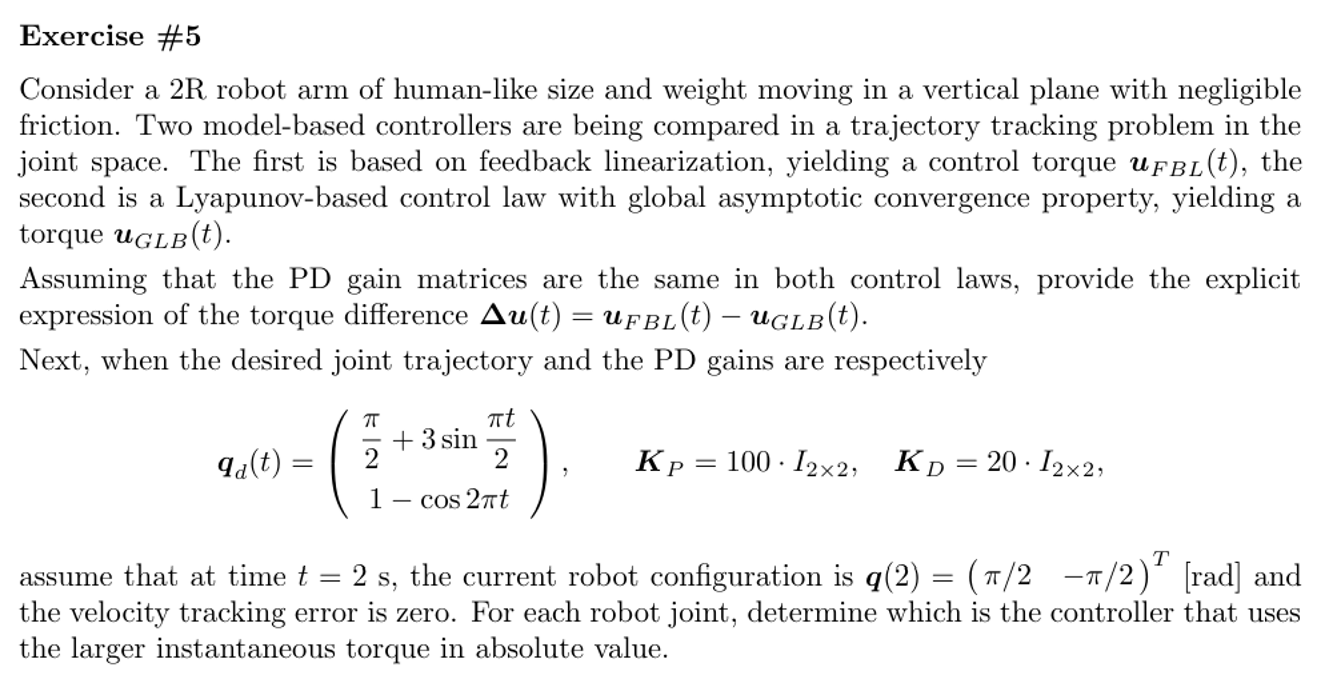

clc; clear;

% Define symbolic variables
syms t q1 q2 real
syms a1 a2 a3 real

% PD gains
I2 = eye(2);
Kp = 100 * I2;
Kd = 20 * I2;

% Desired trajectory and derivatives
qd = [pi/2 + 3*sin(pi*t/2); 
      1 - cos(2*pi*t)];
qd_dot = diff(qd, t);
qd_ddot = diff(qd_dot, t);

% Evaluate desired trajectory at t = 2s
t_val = 2;
qd_val = double(subs(qd, t, t_val));
qd_dot_val = double(subs(qd_dot, t, t_val));
qd_ddot_val = double(subs(qd_ddot, t, t_val));

% Current state at t = 2s
q_val = [pi/2; -pi/2];      % [rad]
q_dot_val = qd_dot_val;     % zero velocity error

% Substitute values for q1, q2
q1 = q_val(1);
q2 = q_val(2);

% Define M(q)
M = [ a1 + 2*a2*cos(q2),  a3 + a2*cos(q2);
      a3 + a2*cos(q2),    a3 ];

% Define S(q,q_dot) such that c(q,q_dot) = S(q,q_dot)*q_dot
% You can derive this analytically or define a symbolic S here:
S = sym('s', [2 2]);  % placeholder for symbolic S

% Compute Δu = (M - I)*(Kd*(qd_dot - q_dot) + Kp*(qd - q)) + S*(q_dot - qd_dot)
delta_u = simplify( ...
    (M - I2)*(Kd*(qd_dot_val - q_dot_val) + Kp*(qd_val - q_val)) + ...
    S*(q_dot_val - qd_dot_val) );

% Display results
disp('Inertia matrix M(q):');

Inertia matrix M(q):


disp(M);

$$\left(\begin{array}{cc} a_{1}+\frac{4967757600021511\,a_{2}}{40564819207303340847894502572032} & \frac{4967757600021511\,a_{2}}{81129638414606681695789005144064}+a_{3}\\ \frac{4967757600021511\,a_{2}}{81129638414606681695789005144064}+a_{3} & a_{3} \end{array}\right)$$


disp('Torque difference Δu(t=2):');

Torque difference Δu(t=2):


disp(eval(delta_u));

$$\left(\begin{array}{c} 50\,\pi \,\left(\frac{4967757600021511\,a_{2}}{81129638414606681695789005144064}+a_{3}\right)\\ 50\,\pi \,\left(a_{3}-1\right) \end{array}\right)$$